Read the input data

filename = "jls_section_8.pdf";
str = extractFileText(filename);
textData = split(str,newline);
documents = tokenizedDocument(textData);

Preprocessing:

Remove stop words like "a", "an", "the", "of", etc, and erase all punctuation marks 

documents = removeStopWords(documents)

documents =   7193×1 tokenizedDocument:

     1 tokens: CHAPTER
     1 tokens: 8
     0 tokens:
     1 tokens: Classes
     0 tokens:
     0 tokens:
    12 tokens: class declaration defines new class describes implemented ( § 8.1 ) .
     0 tokens:
    13 tokens: top level class ( § 7.6 ) class declared directly compilation unit .
     0 tokens:
     8 tokens: nested class class whose declaration occurs body another
    16 tokens: class interface declaration . nested class member class ( § 8.5 , § 9.5 ) ,
    14 tokens: local class ( § 14.3 ) , anonymous class ( § 15.9.5 ) .
     0 tokens:
    11 tokens: kinds nested class inner class ( § 8.1.3 ) , class
    11 tokens: refer enclosing class instances , local variables , type variables .
     0 tokens:
    11 tokens: enum class ( § 8.9 ) class declared abbreviated syntax defines
     6 tokens: small set named class instances .
     0 tokens:
    11 tokens: record 

documents = erasePunctuation(documents)

documents =   7193×1 tokenizedDocument:

     1 tokens: CHAPTER
     1 tokens: 8
     0 tokens:
     1 tokens: Classes
     0 tokens:
     0 tokens:
     8 tokens: class declaration defines new class describes implemented 81
     0 tokens:
     9 tokens: top level class 76 class declared directly compilation unit
     0 tokens:
     8 tokens: nested class class whose declaration occurs body another
     9 tokens: class interface declaration nested class member class 85 95
     6 tokens: local class 143 anonymous class 1595
     0 tokens:
     7 tokens: kinds nested class inner class 813 class
     8 tokens: refer enclosing class instances local variables type variables
     0 tokens:
     8 tokens: enum class 89 class declared abbreviated syntax defines
     5 tokens: small set named class instances
     0 tokens:
     8 tokens: record class 810 class declared abbreviated syntax defines
     3 tokens: simple aggr

Create a LDA model

bag = bagOfWords(documents)

bag =   bagOfWords with properties:

          Counts: [7193×2192 double]
      Vocabulary: ["CHAPTER"    "8"    "Classes"    "class"    "declaration"    "defines"    "new"    "describes"    "implemented"    "81"    "top"    "level"    "76"    "declared"    "directly"    "compilation"    "unit"    "nested"    "whose"    …    ]
        NumWords: 2192
    NumDocuments: 7193


mdl = fitlda(bag,20,'Verbose',0)

mdl =   ldaModel with properties:

                     NumTopics: 20
             WordConcentration: 1
            TopicConcentration: 1.2628
      CorpusTopicProbabilities: [0.0871 0.0721 0.0696 0.0636 0.0626 0.0575 0.0570 0.0532 0.0518 0.0499 0.0474 0.0454 0.0445 0.0431 0.0406 0.0404 0.0399 0.0260 0.0254 0.0230]
    DocumentTopicProbabilities: [7193×20 double]
        TopicWordProbabilities: [2192×20 double]
                    Vocabulary: ["CHAPTER"    "8"    "Classes"    "class"    "declaration"    "defines"    "new"    "describes"    "implemented"    "81"    "top"    "level"    "76"    "declared"    "directly"    "compilation"    "unit"    …    ]
                    TopicOrder: 'initial-fit-probability'
                       FitInfo: [1×1 struct]


Plot the word clouds

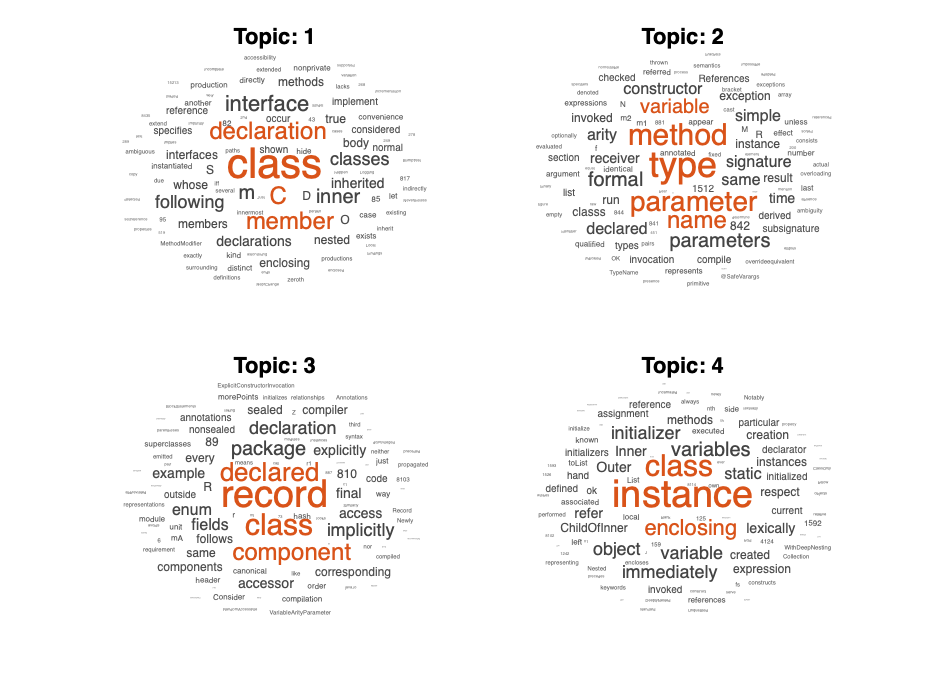

figure
for topicIdx = 1:4
    subplot(2,2,topicIdx)
    wordcloud(mdl,topicIdx);
    title("Topic: " + topicIdx)
end